clear all
close all
clc

# Inverse Dynamics of Cart Pole System

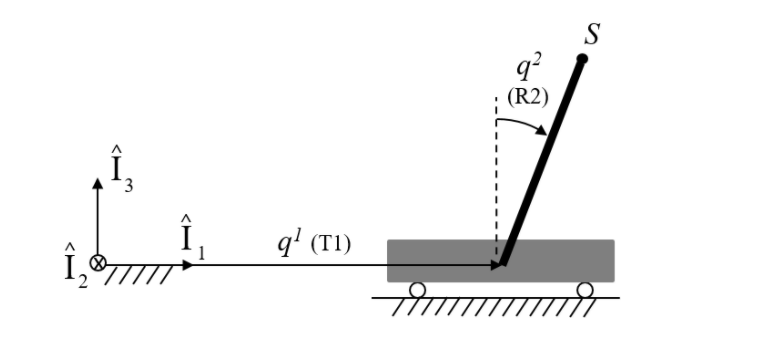

## System Description

The cart translates with respect to the inertial frame in one dimension freely and no external force is applied on the cart. The cart is assumed to be a simple lumped mass block and its inertia and mass is significanty higher than the mass of the pole. This ensures that the motion of the pole doesn't effect the motion of the cart in any way.

The pole is a uniformly distributed stick with its centre of mass at its geometric centre. It rotates with respect to the translating cart with the help of a revolute joint. The system is a lumped parameter system which can be represented by ordinary differential equations.

**The angular motion of the pole is assumed to be very small in order to linearlize the system.**

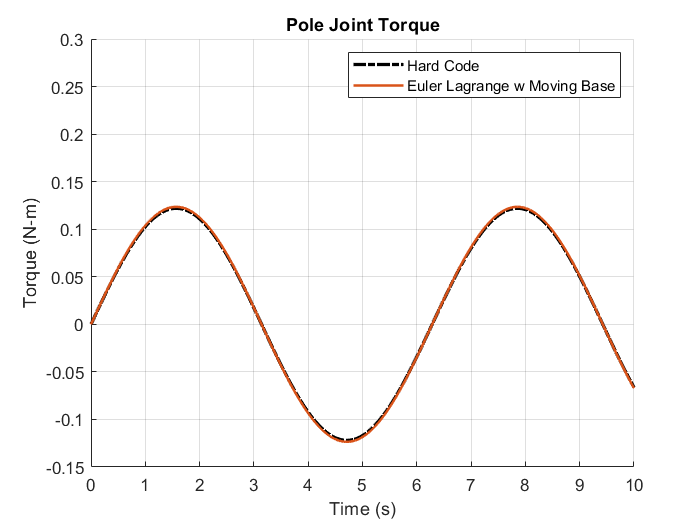

%time vector
t_span = linspace(0,10,1000);

%system parameters
%cart mass
M = 10000;%kg
%the cart mass doesn't have any effect on the torque applied on the
%revolute joint
%logical because the torque has to drive the pole only and thus cart mass
%doesn't matter

%KEpole = 0.5m*v2 + 0.5*I*w2
%I = (1/12)*m*l2;

%Pole mass
m = 50;%kg

%Pole length
L = 0.1;%meters

%pole rotation
theta = 0.005*sin(t_span);%radians

%pole rotation acceleration
theta_dotdot = -0.005*sin(t_span);%radians/second^2

%cart acceleration
x_dotdot = ((m*L)/(m + M))*theta_dotdot;%meters/second^2

%acceleration due to gravity
g = 9.81; %meters/second^2


%Revolute joint torque calculation

torque = ((m*L^2)/(4))*theta_dotdot - (m*L)*x_dotdot + ((m*g*L)/(2))*theta;

%torque calculation from euler lagrange formulation 

% EL_torque = load('EL_code_results.mat');
% el_torque = EL_torque.joint_torques;
% for ii = 1:length(t_span)
%     code_torques(ii) = el_torque{ii};
% end

code_torques = Inv_Dynamics_LE_CartPole;

figure(1)
hold on
plot(t_span,torque,'-.','color','k','linewidth',2)
plot(t_span,code_torques,'linewidth',1.5)
legend('Hard Code','Euler Lagrange w Moving Base')

grid on
title('Pole Joint Torque')
xlabel('Time (s)')
ylabel('Torque (N-m)')
axis([0,10,-0.15,0.3])